# tRGS Test

In this notebook, we're testing an implementation of tensor randomized Gauss Seidel.

addpath('../tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

m = 40;
n = 20;
l = 10;
p = 30;

%generate tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
X_ln = tprod(tpinv(A),B);
[errs,res_errs,ln_errs,res_ln_errs] = tRGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln);

%run some iterations of RGS
matX_ln = tprod(tpinv(matA),matB);
[mat_errs,mat_res_errs,mat_ln_errs,mat_res_ln_errs] = tRGS_err(matA,matB,zeros(n*p,l,1),num_its,matX_true,matX_ln);

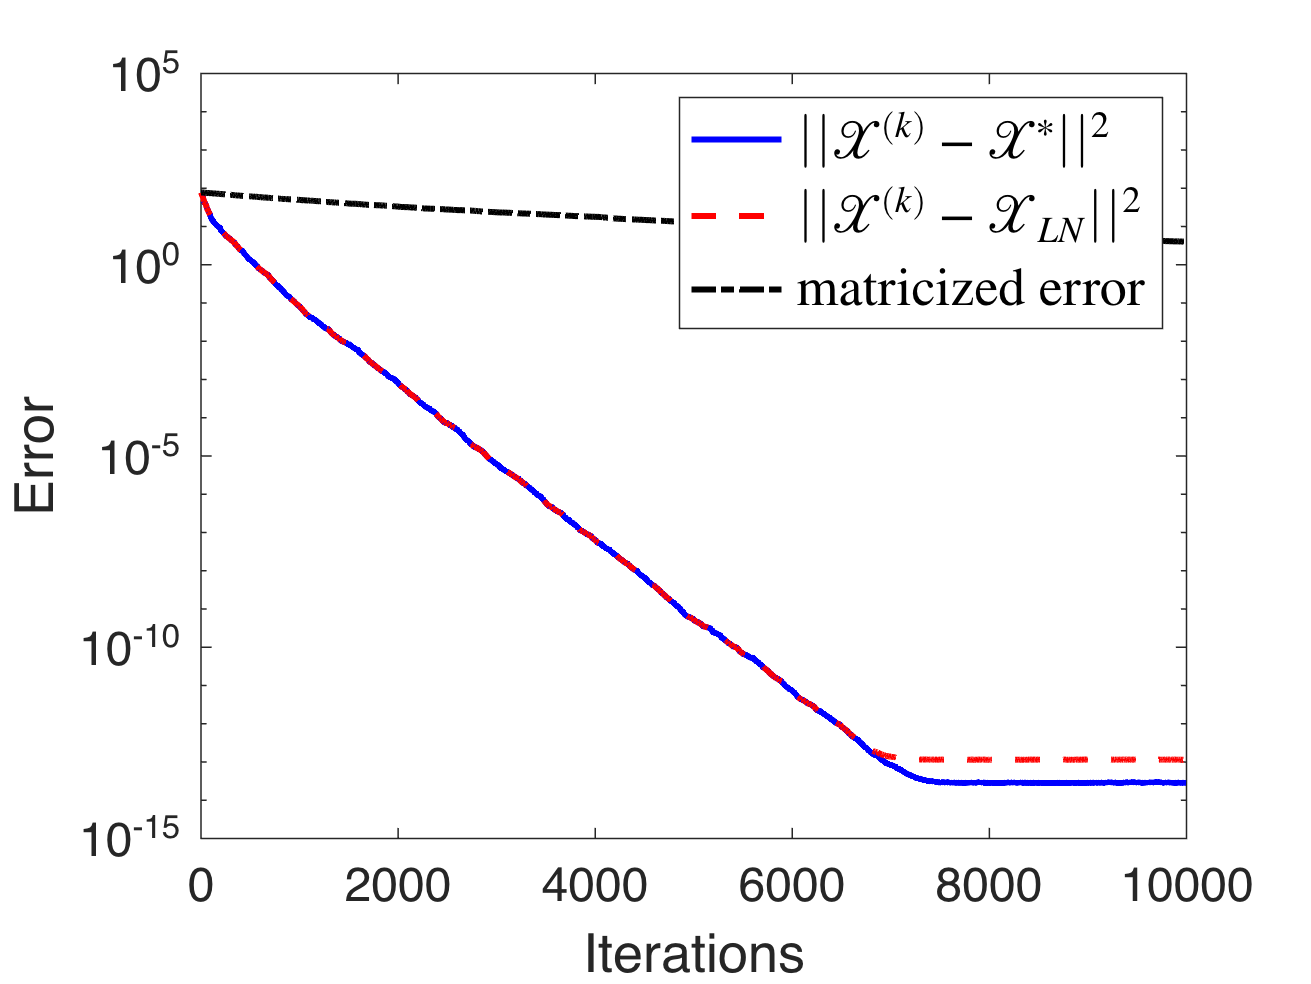

%plot errors vs iterations
figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,ln_errs,'r--',0:num_its,mat_errs,'k-.','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||^2$','matricized error','Interpreter','latex','FontSize',18)
hold off

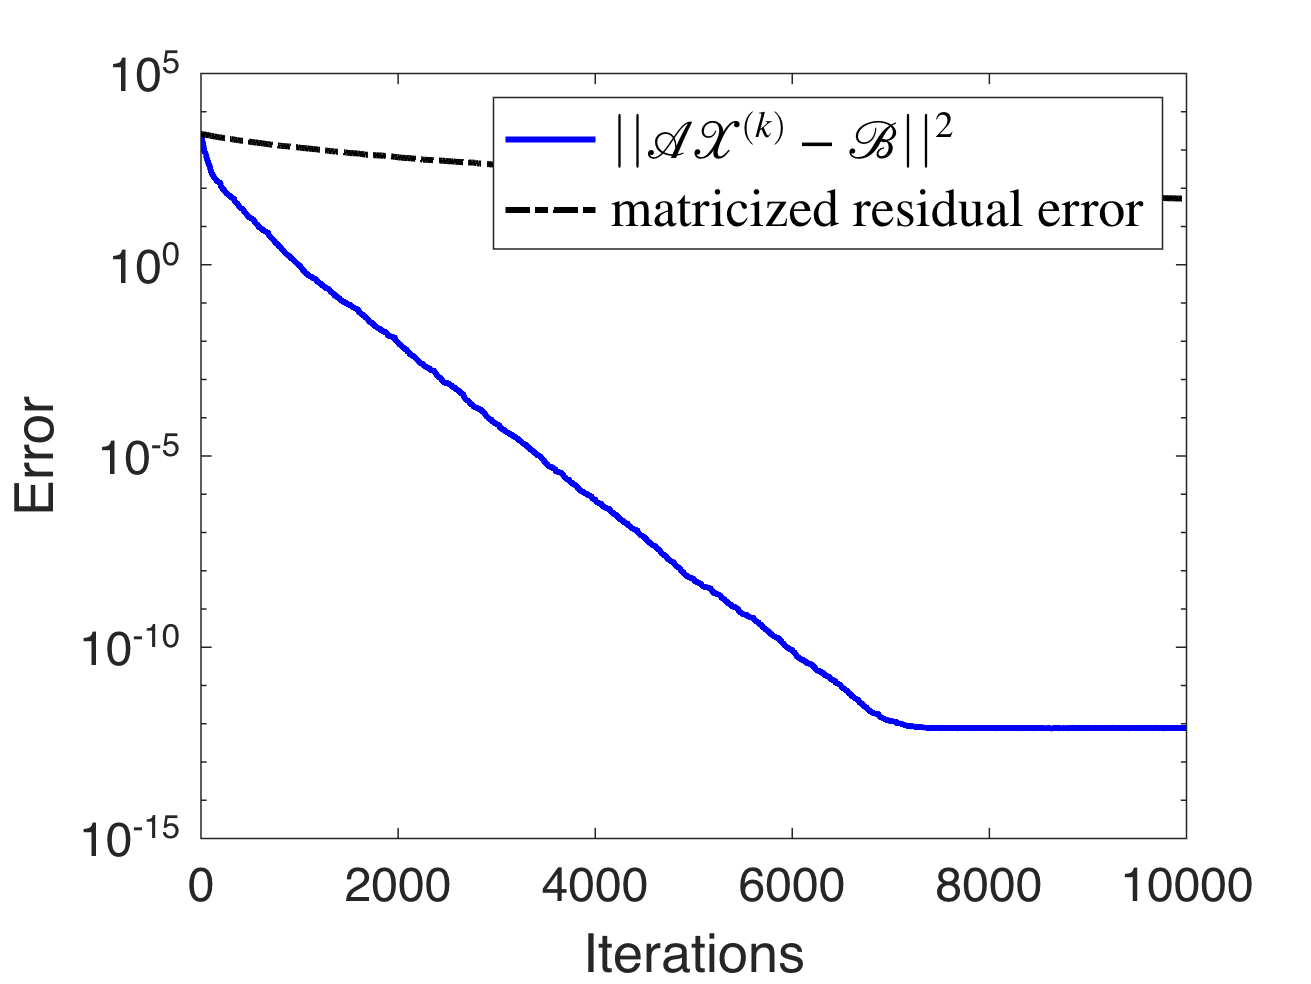

%plot residual errors vs iterations
figure(2);
semilogy(0:num_its,res_errs,'b-',0:num_its,mat_res_errs,'k-.','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{A} \mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized residual error', 'Interpreter','latex','FontSize',18)
hold off

And it appears this implementation is working!